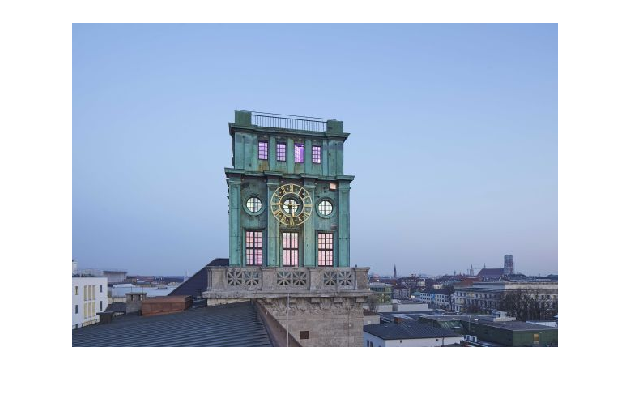

clc;
clear;
close

Image2 = imread('uhren-turm.jpg');
IGray2 = rgb_to_gray(Image2);
figure;
imshow(Image2);



hold on

get the size of the img

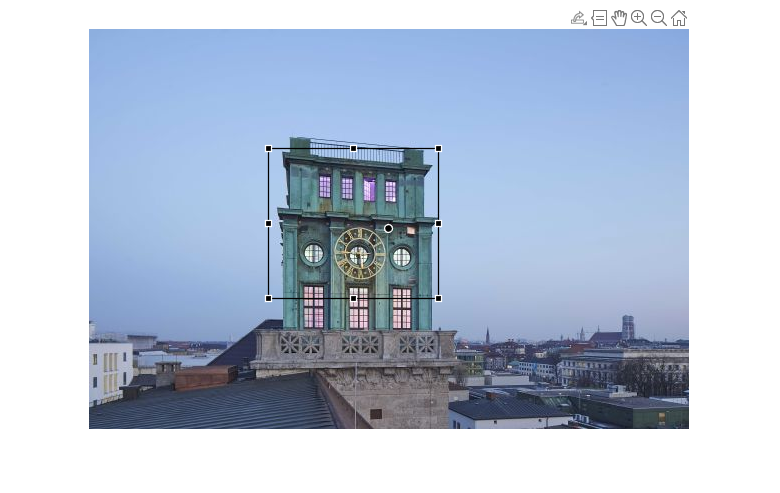

global m;
global n;
global BorderPoint;

[m, n] = size(IGray2);

% Draw vanishing point
% initial VanishingPoint(middle of the Picture)

vb = .5 * (m);
va = .5 * (n);

% plot(va, vb,'r*')
pos_VanishingPoint = [va vb];
roi_VanishingPoint = drawpoint(gca, 'Position', pos_VanishingPoint, "Color", 'k', "LineWidth", 5);
% hold on
% Draw inner rectangle

% [x y w h]= x and y elements determine the location (top-left) and the w and h elements determine the size
pos_InnerRectangle = [0.6 * va, 0.6 * vb, 0.5 * va + 0.1 * vb, 0.5 * va];
roi_InnerRectangle = drawrectangle('Color', 'k', 'FaceAlpha', 0, ...
    'FaceSelectable', (false), 'LineWidth', 1);
roi_InnerRectangle.Position = pos_InnerRectangle;

**Draw 4 radial lines**

l1 = addlistener(roi_VanishingPoint, 'MovingROI', @(src, evt) radialline_vp(src, evt, roi_VanishingPoint, roi_InnerRectangle, IGray2));
l2 = addlistener(roi_InnerRectangle, 'MovingROI', @(src, evt) radialline_ir(src, evt, roi_VanishingPoint, roi_InnerRectangle, IGray2));

% get the position of Vanishing Poit(VP) and Inner Rectangle(IR),

l3 = addlistener(roi_InnerRectangle, 'ROIMoved', @(src, evt) roiChange(src, evt, 'Updated_InnerRectangle'));
l4 = addlistener(roi_VanishingPoint, 'ROIMoved', @(src, evt) roiChange(src, evt, 'Updated_VanishingPoint'));

% initial P

% P = [1,0.5;m,0.5;1,m;n,m];

% P9, P10, P3, P4
P9 = images.roi.Point(gca, "MarkerSize", 1, "Color","r");

% P9.Position = P(1, :);
P10 = images.roi.Point(gca, "MarkerSize", 1, "Color","r");
% P10.Position = P(2, :);
P3 = images.roi.Point(gca, "MarkerSize", 1, "Color","r");
% P3.Position = P(3, :);
P4 = images.roi.Point(gca, "MarkerSize", 1, "Color","r");

% P4.Position = P(4, :);

l5 = addlistener(roi_InnerRectangle, 'ROIMoved', @(r1, evt) BorderPointEvent(roi_InnerRectangle, evt, P9, P10, P3, P4));
l6 = addlistener(roi_VanishingPoint, 'ROIMoved', @(r1, evt) BorderPointEvent(roi_VanishingPoint, evt, P9, P10, P3, P4));



l7 = addlistener(P9, 'MovingROI', @(r1, evt) P9NewVP(P9, evt, P3, P10, P4,roi_InnerRectangle,roi_VanishingPoint));
l8 = addlistener(P3, 'MovingROI', @(r1, evt) P3NewVP(P3, evt, P9,P10, P4, roi_InnerRectangle,roi_VanishingPoint));
l9 = addlistener(P10, 'MovingROI', @(r1, evt) P10NewVP(P10, evt, P4,P9, P3, roi_InnerRectangle,roi_VanishingPoint));
l10 = addlistener(P4, 'MovingROI', @(r1, evt) P4NewVP(P4, evt, P10,P9, P3,roi_InnerRectangle,roi_VanishingPoint));



**functions for radial line**

function radialline_vp(src, evt, vp, rect, img)

global BorderPoint
global BorderPointPlot

BorderPoint = zeros(4, 2);

rect_pos = rect.Position;
% get the inner rectangle position
rect_top_left = [rect_pos(1), rect_pos(2)];
rect_top_right = [rect_pos(1) + rect_pos(3), rect_pos(2)];
rect_bottom_left = [rect_pos(1), rect_pos(2) + rect_pos(4)];
rect_bottom_right = [rect_pos(1) + rect_pos(3), rect_pos(2) + rect_pos(4)];

% save as cell
EdgePoint = {rect_top_left, rect_top_right, rect_bottom_left, rect_bottom_right};

% remove all existing radial lines
allLine = findobj(gcf, 'Type', 'Line');
delete(allLine);

% remove all existing border points
allPoint = findall(gcf, 'Type', 'Point');
delete(allPoint);

% get current vanishing point position
C = evt.CurrentPosition;

RadialLine = zeros(1, 4);
BorderPointPlot = zeros(1, 4);

for x = 1:4
    ThroPoint = EdgePoint{x};
    aLine = TwoPointLine(C, ThroPoint);
    % get border point coordinates
    points = lineToBorderPoints(aLine, size(img));

    %     calcuate the distance from vanishing point (C) to border
    distance_C2Border = pdist([C(1), C(2); points(3), points(4)], 'euclidean');
    %     calcuate the distance from inner rectangle edge to border
    distance_Edge2Border = pdist([ThroPoint(1), ThroPoint(2); points(3), points(4)], 'euclidean');

    if distance_C2Border > distance_Edge2Border

        RadialLine(x) = plot([C(1), points(3)], [C(2), points(4)], 'Color', 'r', 'LineWidth', 2);
        BorderPointPlot(x) = plot(points(3), points(4),'-s', 'MarkerSize', 10, ...
            'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'r');

        BorderPoint(x, :) = [points(3) points(4)];

    else
        RadialLine(x) = plot([C(1), points(1)], [C(2), points(2)], 'Color', 'r', 'LineWidth', 2);
        BorderPointPlot(x) = plot(points(1), points(2),'-s', 'MarkerSize', 10, ...
            'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'r');

        BorderPoint(x, :) = [points(1) points(2)];

    end

    %     make sure that vanishing point is on the top layer
    uistack(RadialLine(x), 'down', 2);
    uistack(BorderPointPlot(x),'down',2);
    uistack(vp, 'up', 2);
    uistack(rect, 'up', 2);

    %         save borderPoints to Workspace
    %     assignin('base', 'Updated_BorderPoint', BorderPoint);

end

end

function radialline_ir(src, evt, vp, rect, img)

global BorderPoint
global BorderPointPlot

% BorderPoint = zeros(4, 2);

% get current inner rectangle position
rect_pos = evt.CurrentPosition;

rect_top_left = [rect_pos(1), rect_pos(2)];
rect_top_right = [rect_pos(1) + rect_pos(3), rect_pos(2)];
rect_bottom_left = [rect_pos(1), rect_pos(2) + rect_pos(4)];
rect_bottom_right = [rect_pos(1) + rect_pos(3), rect_pos(2) + rect_pos(4)];

EdgePoint = {rect_top_left, rect_top_right, rect_bottom_left, rect_bottom_right};

% remove all existing radial lines
allLine = findobj(gcf, 'Type', 'Line');
delete(allLine);

% get the vanishing point position
C = vp.Position;

RadialLine = zeros(1, 4);
% BorderPointPlot = zeros(1, 4);

for x = 1:4
    ThroPoint = EdgePoint{x};
    aLine = TwoPointLine(C, ThroPoint);
    % get border point coordinates
    points = lineToBorderPoints(aLine, size(img));

    %     calcuate the distance from vanishing point (C) to border
    distance_C2Border = pdist([C(1), C(2); points(3), points(4)], 'euclidean');

    %     calcuate the distance from inner rectangle edge to border
    distance_Edge2Border = pdist([ThroPoint(1), ThroPoint(2); points(3), points(4)], 'euclidean');

    if distance_C2Border > distance_Edge2Border

        RadialLine(x) = line([C(1), points(3)], [C(2), points(4)], 'Color', 'r', 'LineWidth', 2);
                BorderPointPlot(x) = plot(points(3), points(4),'-s', 'MarkerSize', 10, ...
            'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'r');

        BorderPoint(x, :) = [points(3) points(4)];
    else
        RadialLine(x) = line([C(1), points(1)], [C(2), points(2)], 'Color', 'r', 'LineWidth', 2);
                BorderPointPlot(x) = plot(points(1), points(2),'-s', 'MarkerSize', 10, ...
            'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'r');
        BorderPoint(x, :) = [points(1) points(2)];
    end

    %     make sure that vanishing point is on the top layer
    uistack(RadialLine(x), 'down', 5);
    uistack(vp, 'up', 2);
    uistack(rect, 'up', 2);

    %     assignin('base', 'Updated_BorderPoint', BorderPoint);
end

end

function aLine = TwoPointLine(C, ThroPoint)
% coefficients = polyfit([x1 x2], [y1 y2], 1);
coefficients = polyfit([C(1) ThroPoint(1)], [C(2) ThroPoint(2)], 1);
a = coefficients (1);
b = coefficients (2);
% Define a line with the equation, a * x + y + b = 0.
aLine = [a, -1, b];

end

function roi = roiChange(~, evt, roi)
assignin('base', roi, evt.CurrentPosition);
end

function BorderPointEvent(~, ~, roi9, roi10, roi3, roi4)

global BorderPoint

P = BorderPoint;
roi9.Position = P(1, :);
roi10.Position = P(2, :);
roi3.Position = P(3, :);
roi4.Position = P(4, :);

% uistack(BorderPointPlot, 'down', 5);
uistack(roi9, 'up', 8);
uistack(roi10, 'up', 8);
uistack(roi3, 'up', 8);
uistack(roi4, 'up', 8);
end

function P9NewVP(roi1, evt, roi2,roi3, roi4,rect,vp)

%     global BorderPoint
% global BorderPointPlot
global m
global n

rect_pos = rect.Position;
% get the inner rectangle position
% rect_top_left = [rect_pos(1), rect_pos(2)];
rect_top_right = [rect_pos(1) + rect_pos(3), rect_pos(2)];
rect_bottom_left = [rect_pos(1), rect_pos(2) + rect_pos(4)];
rect_bottom_right = [rect_pos(1) + rect_pos(3), rect_pos(2) + rect_pos(4)];

EdgePoint = {rect_bottom_left, rect_top_right, rect_bottom_right};

allLine = findobj(gcf, 'Type', 'Line');
delete(allLine);

roi1_pos = evt.CurrentPosition;
roi2_pos = roi2.Position;



%line1
x1  = [roi1_pos(1) rect_pos(1)];
y1  = [roi1_pos(2) rect_pos(2)];
%line2
x2  = [roi2_pos(1) rect_pos(1)];
y2  = [roi2_pos(2) rect_pos(2) + rect_pos(4)];


% p1 = polyfit(x1,y1,1);
% p2 = polyfit(x2,y2,1);

p1 = polyfit(x1,y1,1);
p2 = polyfit(x2,y2,1);

%calculate intersection
x_intersect = fzero(@(x) polyval(p1-p2,x),3);
y_intersect = polyval(p1,x_intersect);

vp.Position = [x_intersect, y_intersect];
vp_pos = [x_intersect, y_intersect];
% uistack(BorderPointPlot, 'down', 5);
% uistack(roi1, 'up', 2);
% uistack(roi2, 'up', 2);


roi = cell(1,3);
RadialLine = zeros(1, 3);
for x = 1:3
    ThroPoint = EdgePoint{x};
    aLine = TwoPointLine(vp_pos, ThroPoint);
    % get border point coordinates
    points = lineToBorderPoints(aLine, [m,n]);
    
    %     calcuate the distance from vanishing point (C) to border
    distance_C2Border = pdist([vp_pos(1), vp_pos(2); points(3), points(4)], 'euclidean');
    
    %     calcuate the distance from inner rectangle edge to border
    distance_Edge2Border = pdist([ThroPoint(1), ThroPoint(2); points(3), points(4)], 'euclidean');
    
    if distance_C2Border > distance_Edge2Border
            roi_pos = [points(3), points(4)];
            
            RadialLine(x) = line([roi_pos(1), vp.Position(1)], [roi_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);    
    else
            roi_pos = [points(1), points(2)];
            
            RadialLine(x) = line([roi_pos(1), vp.Position(1)], [roi_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);
    end
    roi{x} = roi_pos;

end

roi2.Position = roi{1};
roi3.Position = roi{2};
roi4.Position = roi{3};

line([roi1_pos(1), vp.Position(1)], [roi1_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);

uistack(vp, 'up', 7);
uistack(roi1, 'up', 6);
uistack(roi2, 'up', 6);
uistack(roi3, 'up', 6);
uistack(roi4, 'up', 6);

end

function P3NewVP(roi1, evt, roi2,roi3, roi4,rect,vp)

%     global BorderPoint
% global BorderPointPlot
global m
global n

rect_pos = rect.Position;
% get the inner rectangle position
rect_top_left = [rect_pos(1), rect_pos(2)];
rect_top_right = [rect_pos(1) + rect_pos(3), rect_pos(2)];
% rect_bottom_left = [rect_pos(1), rect_pos(2) + rect_pos(4)];
rect_bottom_right = [rect_pos(1) + rect_pos(3), rect_pos(2) + rect_pos(4)];

EdgePoint = {rect_top_left, rect_top_right, rect_bottom_right};

allLine = findobj(gcf, 'Type', 'Line');
delete(allLine);

roi1_pos = evt.CurrentPosition;
roi2_pos = roi2.Position;



%line1
x1  = [roi1_pos(1) rect_pos(1)];
y1  = [roi1_pos(2) rect_pos(2) + rect_pos(4)];
%line2
x2  = [roi2_pos(1) rect_pos(1)];
y2  = [roi2_pos(2) rect_pos(2)];


% p1 = polyfit(x1,y1,1);
% p2 = polyfit(x2,y2,1);

p1 = polyfit(x1,y1,1);
p2 = polyfit(x2,y2,1);

%calculate intersection
x_intersect = fzero(@(x) polyval(p1-p2,x),3);
y_intersect = polyval(p1,x_intersect);

vp.Position = [x_intersect, y_intersect];
vp_pos = [x_intersect, y_intersect];
% uistack(BorderPointPlot, 'down', 5);
% uistack(roi1, 'up', 2);
% uistack(roi2, 'up', 2);


roi = cell(1,3);
RadialLine = zeros(1, 3);
for x = 1:3
    ThroPoint = EdgePoint{x};
    aLine = TwoPointLine(vp_pos, ThroPoint);
    % get border point coordinates
    points = lineToBorderPoints(aLine, [m,n]);
    
    %     calcuate the distance from vanishing point (C) to border
    distance_C2Border = pdist([vp_pos(1), vp_pos(2); points(3), points(4)], 'euclidean');
    
    %     calcuate the distance from inner rectangle edge to border
    distance_Edge2Border = pdist([ThroPoint(1), ThroPoint(2); points(3), points(4)], 'euclidean');
    
    if distance_C2Border > distance_Edge2Border
            roi_pos = [points(3), points(4)];
            
            RadialLine(x) = line([roi_pos(1), vp.Position(1)], [roi_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);    
    else
            roi_pos = [points(1), points(2)];
            
            RadialLine(x) = line([roi_pos(1), vp.Position(1)], [roi_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);
    end
    roi{x} = roi_pos;

end

roi2.Position = roi{1};
roi3.Position = roi{2};
roi4.Position = roi{3};

line([roi1_pos(1), vp.Position(1)], [roi1_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);

uistack(vp, 'up', 7);
uistack(roi1, 'up', 6);
uistack(roi2, 'up', 6);
uistack(roi3, 'up', 6);
uistack(roi4, 'up', 6);


end

function P10NewVP(roi1, evt, roi2,roi3, roi4,rect,vp)


global m
global n

rect_pos = rect.Position;
% get the inner rectangle position
rect_top_left = [rect_pos(1), rect_pos(2)];
% rect_top_right = [rect_pos(1) + rect_pos(3), rect_pos(2)];
rect_bottom_left = [rect_pos(1), rect_pos(2) + rect_pos(4)];
rect_bottom_right = [rect_pos(1) + rect_pos(3), rect_pos(2) + rect_pos(4)];

EdgePoint = {rect_bottom_right, rect_top_left, rect_bottom_left};

allLine = findobj(gcf, 'Type', 'Line');
delete(allLine);

roi1_pos = evt.CurrentPosition;
roi2_pos = roi2.Position;



%line1
x1  = [roi1_pos(1) rect_pos(1) + rect_pos(3)];
y1  = [roi1_pos(2) rect_pos(2)];
%line2
x2  = [roi2_pos(1) rect_pos(1) + rect_pos(3)];
y2  = [roi2_pos(2) rect_pos(2) + rect_pos(4)];



% p1 = polyfit(x1,y1,1);
% p2 = polyfit(x2,y2,1);

p1 = polyfit(x1,y1,1);
p2 = polyfit(x2,y2,1);

%calculate intersection
x_intersect = fzero(@(x) polyval(p1-p2,x),3);
y_intersect = polyval(p1,x_intersect);

vp.Position = [x_intersect, y_intersect];
vp_pos = [x_intersect, y_intersect];
% uistack(BorderPointPlot, 'down', 5);
% uistack(roi1, 'up', 2);
% uistack(roi2, 'up', 2);


roi = cell(1,3);
RadialLine = zeros(1, 3);
for x = 1:3
    ThroPoint = EdgePoint{x};
    aLine = TwoPointLine(vp_pos, ThroPoint);
    % get border point coordinates
    points = lineToBorderPoints(aLine, [m,n]);
    
    %     calcuate the distance from vanishing point (C) to border
    distance_C2Border = pdist([vp_pos(1), vp_pos(2); points(3), points(4)], 'euclidean');
    
    %     calcuate the distance from inner rectangle edge to border
    distance_Edge2Border = pdist([ThroPoint(1), ThroPoint(2); points(3), points(4)], 'euclidean');
    
    if distance_C2Border > distance_Edge2Border
            roi_pos = [points(3), points(4)];
            
            RadialLine(x) = line([roi_pos(1), vp.Position(1)], [roi_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);    
    else
            roi_pos = [points(1), points(2)];
            
            RadialLine(x) = line([roi_pos(1), vp.Position(1)], [roi_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);
    end
    roi{x} = roi_pos;

end

roi2.Position = roi{1};
roi3.Position = roi{2};
roi4.Position = roi{3};

line([roi1_pos(1), vp.Position(1)], [roi1_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);

uistack(vp, 'up', 7);
uistack(roi1, 'up', 6);
uistack(roi2, 'up', 6);
uistack(roi3, 'up', 6);
uistack(roi4, 'up', 6);

end

function P4NewVP(roi1, evt, roi2,roi3, roi4,rect,vp)


%     global BorderPoint
% global BorderPointPlot
global m
global n

rect_pos = rect.Position;
% get the inner rectangle position
rect_top_left = [rect_pos(1), rect_pos(2)];
rect_top_right = [rect_pos(1) + rect_pos(3), rect_pos(2)];
rect_bottom_left = [rect_pos(1), rect_pos(2) + rect_pos(4)];
% rect_bottom_right = [rect_pos(1) + rect_pos(3), rect_pos(2) + rect_pos(4)];

EdgePoint = {rect_top_right, rect_top_left, rect_bottom_left};

allLine = findobj(gcf, 'Type', 'Line');
delete(allLine);

roi1_pos = evt.CurrentPosition;
roi2_pos = roi2.Position;



%line1
x1  = [roi1_pos(1) rect_pos(1) + rect_pos(3)];
y1  = [roi1_pos(2) rect_pos(2) + rect_pos(4)];
%line2
x2  = [roi2_pos(1) rect_pos(1) + rect_pos(3)];
y2  = [roi2_pos(2) rect_pos(2)];


% p1 = polyfit(x1,y1,1);
% p2 = polyfit(x2,y2,1);

p1 = polyfit(x1,y1,1);
p2 = polyfit(x2,y2,1);

%calculate intersection
x_intersect = fzero(@(x) polyval(p1-p2,x),3);
y_intersect = polyval(p1,x_intersect);

vp.Position = [x_intersect, y_intersect];
vp_pos = [x_intersect, y_intersect];
% uistack(BorderPointPlot, 'down', 5);
% uistack(roi1, 'up', 2);
% uistack(roi2, 'up', 2);


roi = cell(1,3);
RadialLine = zeros(1, 3);
for x = 1:3
    ThroPoint = EdgePoint{x};
    aLine = TwoPointLine(vp_pos, ThroPoint);
    % get border point coordinates
    points = lineToBorderPoints(aLine, [m,n]);
    
    %     calcuate the distance from vanishing point (C) to border
    distance_C2Border = pdist([vp_pos(1), vp_pos(2); points(3), points(4)], 'euclidean');
    
    %     calcuate the distance from inner rectangle edge to border
    distance_Edge2Border = pdist([ThroPoint(1), ThroPoint(2); points(3), points(4)], 'euclidean');
    
    if distance_C2Border > distance_Edge2Border
            roi_pos = [points(3), points(4)];
            
            RadialLine(x) = line([roi_pos(1), vp.Position(1)], [roi_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);    
    else
            roi_pos = [points(1), points(2)];
            
            RadialLine(x) = line([roi_pos(1), vp.Position(1)], [roi_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);
    end
    roi{x} = roi_pos;

end

roi2.Position = roi{1};
roi3.Position = roi{2};
roi4.Position = roi{3};

line([roi1_pos(1), vp.Position(1)], [roi1_pos(2), vp.Position(2)], 'Color', 'r', 'LineWidth', 2);

uistack(vp, 'up', 7);
uistack(roi1, 'up', 6);
uistack(roi2, 'up', 6);
uistack(roi3, 'up', 6);
uistack(roi4, 'up', 6);


end